## Defining directories

You need to add AQuA to your path in order to use its functions

softwareDir = 'Z:/.code/AQuA/'; %AQuA path
addpath(genpath(softwareDir));

%  read features from movies and put all the information in one structure called out
datDir = 'data/processed/v26/v26.aqua.data/'; %input directory where all of your processed movies are (aqua's .mat)
outDir = 'interim/v26.interim/';

spRes = 0.57998046875; %um/pix
tRes = 0.55578697729921; %sec/frame

## Read features from all movies, store in a structure called out

% you might need to rewrite parts of this function or use your own function
% for reading in the data. When I was doing this analysis, we had AQuA
% writing the output in a strucutre called res. One layer deep was a
% substructure called fts and a layer deeper into fts was substructures like
% propagation, network, etc. The output format has changed a bit
% over time, so this function might be a little outdated. 

disp(pwd)

C:\Users\camer\Box\CMH\.repos\pfc


out = readFts(datDir);

     1

below
121219_V26_54um_2x-000_video_aqua
     2

below
121219_V26_59um_2x-000_video_aqua
     3

below
121219_V26_test2-000_video_aqua
     4

below
121219_V26_test2-000_video_aqua
     5

below
121619_10min_67um_nopupil_2x-002_video_aqua
     6

below
121619_10min_67um_nopupil_2x-002_video_aqua


Has read in the data from all aqua videos in v26 dir 

Want to see what structure looks like

test = fieldnamesr(out)

test = 25×1 cell array
    {'dffMat'                }
    {'xSize'                 }
    {'ySize'                 }
    {'zSize'                 }
    {'datNames'              }
    {'propGrow'              }
    {'propGrowOverall'       }
    {'propSpeedPerFrameDArea'}
    {'propSpeedPerFrame'     }
    {'dff'                   }
    {'dffMaxFrame'           }
    {'dffRise'               }
    {'dffFall'               }
    {'pixelSizePerFrame'     }
    {'t0'                    }
    {'t1'                    }
    {'tBegin'                }
    {'tEng'                  }
    {'allSize'               }
    {'duration55'            }
    {'duration11'            }
    {'loc2D'                 }
    {'locAbs'                }
    {'network'               }
    {'networkNumEvts'        }


test

test = 25×1 cell array
    {'dffMat'                }
    {'xSize'                 }
    {'ySize'                 }
    {'zSize'                 }
    {'datNames'              }
    {'propGrow'              }
    {'propGrowOverall'       }
    {'propSpeedPerFrameDArea'}
    {'propSpeedPerFrame'     }
    {'dff'                   }
    {'dffMaxFrame'           }
    {'dffRise'               }
    {'dffFall'               }
    {'pixelSizePerFrame'     }
    {'t0'                    }
    {'t1'                    }
    {'tBegin'                }
    {'tEng'                  }
    {'allSize'               }
    {'duration55'            }
    {'duration11'            }
    {'loc2D'                 }
    {'locAbs'                }
    {'network'               }
    {'networkNumEvts'        }


structree(out, 'data/testing/outtree')

Have made  a structree file - continuing here

tree = 'data/testing/outtree'

tree = 'data/testing/outtree'

treeplot(tree)

Error using sparse
Index exceeds array bounds.

Error in treelayout (line 39)
    A = sparse (parent(j), j, 1, n, n);

Error in treeplot (line 18)
[x,y,h]=treelayout(p);

structstruct(out)

 
out:  [1x1] struct
  |--dffMat:  [1x6] cell
  |--xSize:  [1x6] cell
  |--ySize:  [1x6] cell
  |--zSize:  [1x6] cell
  |--datNames:  [1x6] cell
  |--propGrow:  [1x6] cell
  |--propGrowOverall:  [1x6] cell
  |--propSpeedPerFrameDArea:  [1x6] cell
  |--propSpeedPerFrame:  [1x6] cell
  |--dff:  [1x6] cell
  |--dffMaxFrame:  [1x6] cell
  |--dffRise:  [1x6] cell
  |--dffFall:  [1x6] cell
  |--pixelSizePerFrame:  [1x6] cell
  |--t0:  [1x6] cell
  |--t1:  [1x6] cell
  |--tBegin:  [1x6] cell
  |--tEng:  [1x6] cell
  |--allSize:  [1x6] cell
  |--duration55:  [1x6] cell
  |--duration11:  [1x6] cell
  |--loc2D:  [1x6] cell
  |--locAbs:  [1x6] cell
  |--network:  [1x6] cell
  '--networkNumEvts:  [1x6] cell
 


Plotting percEvts


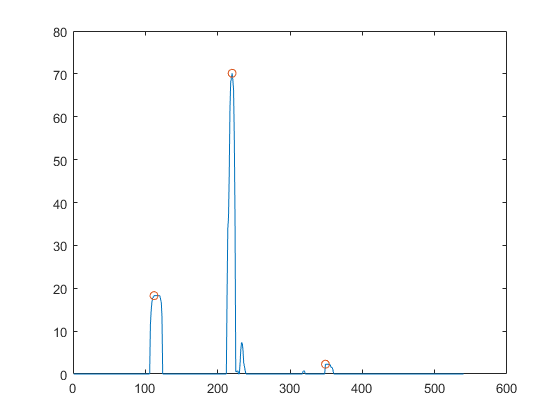

Plotting num events


_____BASELINES_____
Baseline Number of Events:
     1

Baseline percEvents:
   27.5680

n is
     1

window is
  Columns 1 through 5

    92    93    94    95    96

  Columns 6 through 10

    97    98    99   100   101

  Columns 11 through 15

   102   103   104   105   106

  Columns 16 through 20

   107   108   109   110   111

  Columns 21 through 25

   112   113   114   115   116

  Column 26

   117



ans = 'Burst at time 112 does not reach  > baseline '

n is
     2

window is
  Columns 1 through 5

   200   201   202   203   204

  Columns 6 through 10

   205   206   207   208   209

  Columns 11 through 15

   210   211   212   213   214

  Columns 16 through 20

   215   216   217   218   219

  Columns 21 through 25

   220   221   222   223   224

  Column 26

   225

_____xx Detected Burst xx______
bursts{jj}(n,1)
   212

n is
     3

window is
  Columns 1 through 5

   329   330   331   332   333

  Columns 6 through 10

   334   335   336   337   338

  Columns 11 through 15

   339   340   341   342   343

  Columns 16 through 20

   344   345   346   347   348

  Columns 21 through 25

   349   350   351   352   353

  Column 26

   354



ans = 'Burst at time 349 does not reach  > baseline '

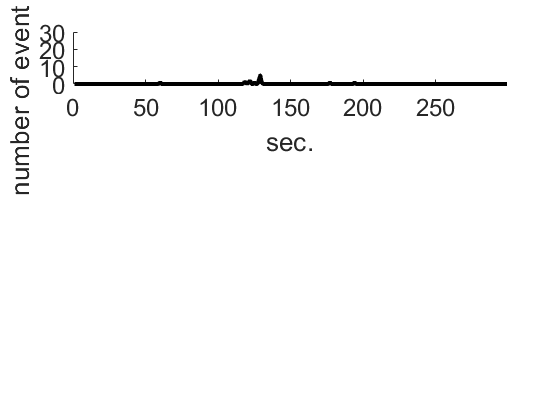

Unrecognized function or variable 'linspecer'.

Error in CdetectBurst (line 394)
        C = linspecer(N,'qualitative');

[bursts, bursStats] = CdetectBurst(out, spRes, tRes, outDir)